Phys3605 - Fall 2024: Homework 3

**Problem 1: Linear Fit and Kai Squared**

**1.**

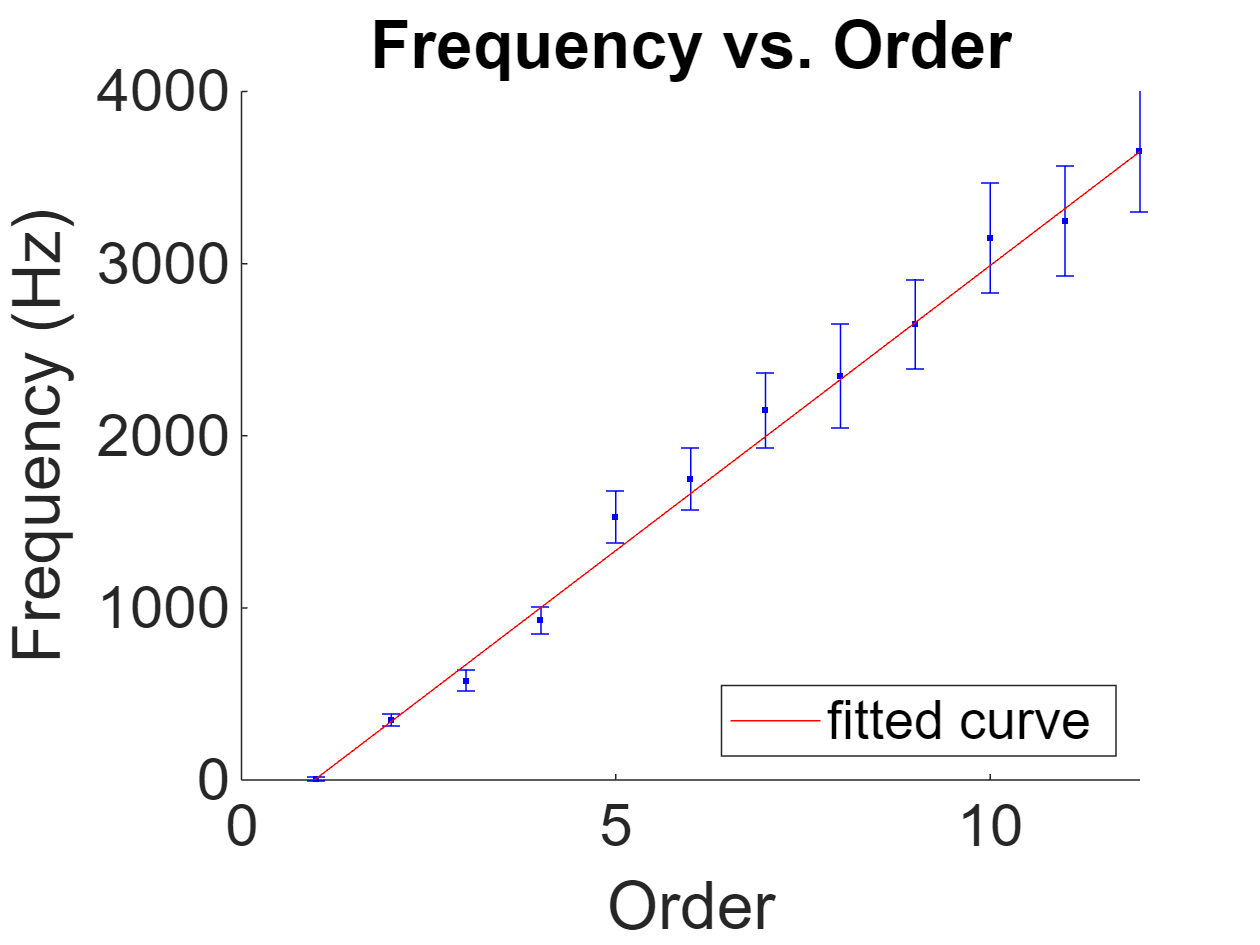

% Initial variables
freq = [10, 350, 580, 930, 1530, 1750, 2150, 2350, 2650, 3150, 3250, 3660] ;
freq_err = [10, 35, 60, 80, 150, 180, 220, 300, 260, 320, 320, 360] ;
order = 1:12 ;
% Calculate weights for use in fit functions
weights = 1./freq_err.^2 ;
% Call fit function
f = fit(order', freq', 'poly1', 'weights', weights) ;
% Plot fit function vs order
hold on
plot(order, freq, "b.")
errorbar(freq, freq_err, 'LineStyle', 'none', 'Color', 'blue')
plot(f)
hold off
xlabel('Order')
ylabel('Frequency (Hz)')
set(gca, "fontsize", 20)
legend('Location', 'southeast')
ylim([0, 4000])
xlim([0, 12])
title('Frequency vs. Order')

**2.**

clf
% Call function to find fit line with weighted least squares approach and
% use the output to get a line (fit_line)
wlsf = wlsfit(order, freq, freq_err) ;
fit_line = wlsf(1) + wlsf(2)*order ;

**3 + 6.**

% Plot new fit line function against old fit line function and the rest of
% the data to check if it is correct
hold on
plot(order, freq, '.', 'Color', 'magenta')
errorbar(freq, freq_err, 'LineStyle', 'none', 'Color', 'magenta')
plot(f, 'b')
plot(order, fit_line, 'r--', 'LineWidth', 2)
hold off
xlabel('Order')
ylabel('Frequency (Hz)')
set(gca, "fontsize", 20)
legend('data', '', 'fit function', 'WLS fit','Location', 'southeast')
ylim([0, 4000])
xlim([0, 12])
title('Frequency vs. Order')

**5.**

% Call function made for finding chi square and chi square reduced
chi_squares = findChi(order, freq, freq_err, wlsf(1), wlsf(2))  ;
string = ['Chi square: ', num2str(chi_squares(1, 1)), ' Chi square reduced: ', num2str(chi_squares(1, 2))] ;
disp(string)

Chi square: 5.9613 Chi square reduced: 0.59613


string = ['Fit slope: ', num2str(wlsf(2)), ' Fit intercept: ', num2str(wlsf(1))] ;
disp(string)

Fit slope: 331.1524 Fit intercept: -322.4178


string = ['Fit slope error: ', num2str(wlsf(4)), ' Fit intercept error: ', num2str(wlsf(3))] ;
disp(string)

Fit slope error: 10.4928 Fit intercept error: 16.052


**4.**

% Function for finding chi-square and reduced chi-square with poly1 as the
% fit
function chi = findChi(x, y, y_uncer, A, B)
    chi_square = sum((y - A - B*x).^2 ./ y_uncer.^2) ;
    chi_square_reduced = chi_square / (length(y) - 2) ;
    chi = [chi_square, chi_square_reduced] ;
end
% Function for calculating linear fit by weighted least squares
function fit = wlsfit(x, y, y_uncer)
    weights = 1 ./ y_uncer.^2 ;
    delta = sum(weights)*sum(weights.*(x.^2)) - (sum(weights.*x))^2 ;
    A = (sum(weights.*x.^2)*sum(weights.*y) - sum(weights.*x)*sum(weights.*x.*y)) / delta ;
    B = (sum(weights)*sum(weights.*x.*y) - sum(weights.*x)*sum(weights.*y)) / delta ; 
    A_err = sqrt(sum(weights.*x.^2) / delta) ;
    B_err = sqrt(sum(weights) / delta) ;
    fit = [A, B, A_err, B_err] ;
end